# DSP Simulation Assignment 2

### Speaker Verification Module

#### Rudrajyoti (18EC10047), Aishik (18EC10074), Swarnava (18EC10070), Debjoy (18EC30010)

#### 1) Gathering the audio files

clc
clear all
close all

myDir = uigetdir; %gets directory
% Add that folder plus all subfolders to the path.
addpath(genpath(myDir));
myFiles = dir(fullfile(myDir,'**\*.wav')); %gets all wav files in struct

#### 2) Construction of the Filters

Nfilters = 20;
Fs = 8000;

z1 = linspace(0,1000,Nfilters/2+1);
z2 = linspace(1000,4000,Nfilters/2+1);
z = unique([z1 z2]);
% z=linspace(0, Fs/2, Nfilters+1);

for i = 1:Nfilters
    if (i==1)
        [b{i}, a{i}] = butter(5,z(i+1)/(Fs/2));
    elseif (i==Nfilters)
        [b{i}, a{i}] = butter(5,z(i)/(Fs/2),'high');
    else
        [b{i}, a{i}] = butter(5,[z(i)/(Fs/2),z(i+1)/(Fs/2)],'bandpass');
    end
end
fprintf(1, 'Filters Ready \n');

Filters Ready 


labels = [];
voices = {};
drawnow

#### 3) Reading Files, Prepare Labels, Compute Filter Output for Speech Identification

for k = 1:length(myFiles)
    baseFileName = myFiles(k).name;
    fullFileName = fullfile(myFiles(k).folder, baseFileName);
    [~,voice] = fileparts(myFiles(k).folder);
    
    fprintf(1, 'Now reading %s by %s\n', baseFileName, voice);
    c = myFiles(k).name(1);
    e = myFiles(k).name(end-4);
    if c=='m'
        newlabel = voice + "-M" + e;
    else
        newlabel = voice + "-A" + e;
    end
    labels = [labels newlabel];
    voices = [voices voice];
    
    % Read Audio Input
    [x, Fs] = audioread(fullFileName);
    
    % DO Filtering
    t = linspace(0,1,length(x))*length(x)/Fs;
    for i= 1:Nfilters
        y = filter(b{i},a{i},x);
        energy(k,i) = sumsqr(y);
        clear y;
    end
    energy(k,:) = energy(k,:)/max(energy(k,:));
end

Now reading afti1.wav by Nivedita
Now reading afti2.wav by Nivedita
Now reading afti3.wav by Nivedita
Now reading afti4.wav by Nivedita
Now reading morn1.wav by Nivedita
Now reading morn2.wav by Nivedita
Now reading morn3.wav by Nivedita
Now reading morn4.wav by Nivedita
Now reading afti1.wav by Prerna
Now reading afti2.wav by Prerna
Now reading afti3.wav by Prerna
Now reading afti4.wav by Prerna
Now reading morning1.wav by Prerna
Now reading morning2.wav by Prerna
Now reading morning3.wav by Prerna
Now reading morning4.wav by Prerna
Now reading Afterlunch_1.wav by Rudrajyoti
Now reading Afterlunch_2.wav by Rudrajyoti
Now reading Afterlunch_3.wav by Rudrajyoti
Now reading Afterlunch_4.wav by Rudrajyoti
Now reading morning_1.wav by Rudrajyoti
Now reading morning_2.wav by Rudrajyoti
Now reading morning_3.wav by Rudrajyoti
Now reading morning_4.wav by Rudrajyoti
Now reading lunch1.wav by Swarnava
Now reading lunch2.wav by Swarnava
Now reading lunch3.wav by Swarnava
Now reading lunch4.wav 

fprintf(1, 'Reading Complete \n');

Reading Complete 


#### 4) Visualise data after reduction to 2-D using PCA and TSNE

% Data preperation
X = energy;
L = char(voices);

% T-SNE plotting - Change args
figure
rng(1);
Y = tsne(X,'Algorithm','barneshut','NumPCAComponents',Nfilters);
gscatter(Y(:,1),Y(:,2),L,'rkgbm')
title("Speech Visualisation in R^2 space");
xlabel('Dim-1');
ylabel('Dim-2');
% saveas(gcf, 'vis.png')
drawnow

#### 5) Prepare Training and Validation Splits

L = size(X);
all_idx = 1:L(1);
dev_idx = [8, 16, 24, 32];
train_idx = setdiff(all_idx, dev_idx);

% Data splitting
X_train = X(train_idx, :);
Y_train = Y(train_idx, :);
voices_train = voices(train_idx);
X_dev = X(dev_idx, :);
Y_dev = Y(dev_idx, :);
voices_dev = voices(dev_idx);

#### 6) Train the k-NN classifier

% Train KNN
mdl = fitcknn(X_train,voices_train,'NumNeighbors',5,'Standardize',1);

disp("-------------------------------")

-------------------------------


disp("Training Completed .....")

Training Completed .....


% See Accuracy on original N-Dim Data
predictedvoices = predict(mdl, X_train);
correct = 0;
incorrect = 0;
for i = 1:length(voices_train)
    if(strcmp(voices_train{i}, predictedvoices{i}))
        correct = correct+1;
    else
        incorrect = incorrect+1;
    end
end
acc = 100*correct/(correct+incorrect);
disp("Training Accuracy = "+num2str(acc)+"%")

Training Accuracy = 100%



% Make predictions on Validation Set
predictedvoices = predict(mdl, X_dev);
correct = 0;
incorrect = 0;
for i = 1:length(voices_dev)
    if(strcmp(voices_dev{i}, predictedvoices{i}))
        correct = correct+1;
    else
        incorrect = incorrect+1;
    end
end
acc = 100*correct/(correct+incorrect);
disp("Dev Accuracy = "+num2str(acc)+"%")

Dev Accuracy = 100%


#### 7) Visualise k-NN classifier decision boundary on reduced dimension data

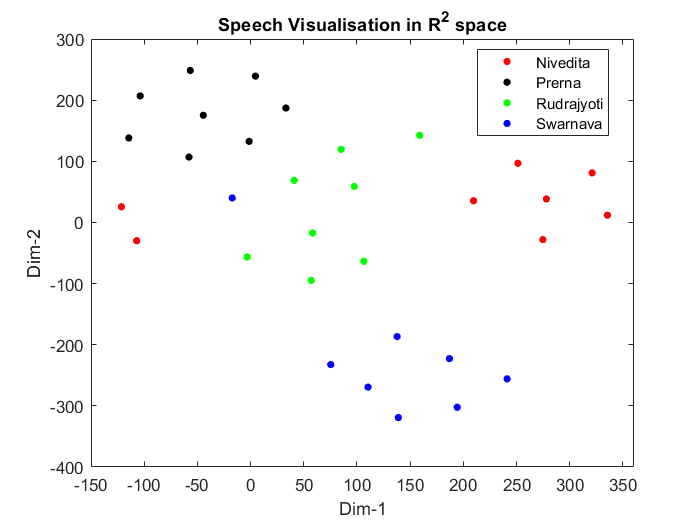

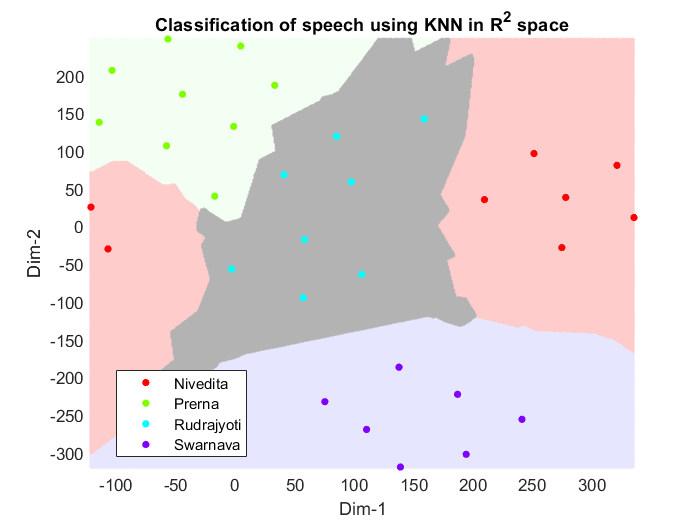

% 2-D data for visualization
mdl_2D = fitcknn(Y_train,voices_train,'NumNeighbors',5,'Standardize',1);
x1range = min(Y(:,1)):1:max(Y(:,1));
x2range = min(Y(:,2)):1:max(Y(:,2));

figure
[xx1, xx2] = meshgrid(x1range,x2range);
XGrid = [xx1(:) xx2(:)];
predictedvoice = predict(mdl_2D,XGrid);
h = gscatter(xx1(:), xx2(:), predictedvoice);
h(1).Color = [0.9 0.9 1];
h(2).Color = [1 0.8 0.8];
h(3).Color = [0.95 1 0.95];  
h(4).Color = [0.7, 0.7, 0.7];
hold on;
title('KNN')
predictedvoiceorg = predict(mdl_2D,Y);
h2 = gscatter(Y(:,1),Y(:,2),predictedvoiceorg);
title("Classification of speech using KNN in R^2 space");
xlabel('Dim-1');
ylabel('Dim-2');
axis tight;
hold off;
% saveas(gcf, 'visualisation.png')
drawnow

#### 8) Get speaker voice mean and deviation measures for speaker verification

category = unique(voices);
energymean = zeros(length(category), Nfilters);
energystd = zeros(length(category), 1);
m = length(voices)/length(category);
maxbound = 0;

for i = 1:length(category)
    % Get Energy Mean
    for k = 1:length(voices)
        if(strcmp(voices(k),category(i)))
            energymean(i,:) = energymean(i,:) + energy(k,:);
        end
    end
    energymean(i,:) = energymean(i,:)/max(energymean(i,:));
    
    % Get Energy Std.Dev
    for k = 1:length(voices)
        if(strcmp(voices(k),category(i)))
            energystd(i) = energystd(i) + sumsqr(energymean(i,:)-energy(k,:));
        end
    end
    energystd(i) = sqrt(energystd(i)/m);
    
    % Get Bound
    for k = 1:length(voices)
        if(strcmp(voices(k),category(i)))
            maxbound = max(maxbound, sqrt(sumsqr(energymean(i,:)-energy(k,:)))/energystd(i));
        end
    end
end

bound_test = (floor(maxbound*10)-1)/10;
disp("Taking bound as "+num2str(bound_test)+" x Standard deviation for each voice ...")

Taking bound as 1.5 x Standard deviation for each voice ...


#### 9) Reading Test-Audio Files, Preparing Test Labels, Computing Filter Output

% Part-2
myDir = uigetdir; %gets directory
% Add that folder plus all subfolders to the path.
addpath(genpath(myDir));
myFiles = dir(fullfile(myDir,'**\*.wav')); % gets all wav files in struct

testlabels = [];
testvoices = {};
for k = 1:length(myFiles)
    baseFileName = myFiles(k).name;
    fullFileName = fullfile(myFiles(k).folder, baseFileName);
    [~,voice] = fileparts(myFiles(k).folder);
    
    fprintf(1, 'Now reading %s by %s\n', baseFileName, voice);
    c = myFiles(k).name(1);
    e = myFiles(k).name(end-4);
    if c=='m'
        newlabel = voice + "-M" + e;
    else
        newlabel = voice + "-A" + e;
    end
    testlabels = [testlabels newlabel];
    testvoices = [testvoices voice];
    
    % Read Audio Input
    [x, Fs] = audioread(fullFileName);
    
    % DO Filtering
    t = linspace(0,1,length(x))*length(x)/Fs;
    for i= 1:Nfilters
        y = filter(b{i},a{i},x);
        testenergy(k,i) = sumsqr(y);
        clear y;
    end
    testenergy(k,:) = testenergy(k,:)/max(testenergy(k,:));
end

Now reading Aishik_lock.wav by Aishik
Now reading Debjoy_Lunch1.wav by Debjoy
Now reading extra.wav by Nivedita
Now reading Test2.wav by Rudrajyoti
Now reading lunch5.wav by Swarnava


fprintf(1, 'Test Reading Complete \n');

Test Reading Complete 


#### 10) Viewing speaker verification performance on the test speech samples

X_test = testenergy;
L_test = char(testvoices);
voices_test = testvoices;

predictedvoices = predict(mdl, X_test);

for k = 1:length(predictedvoices)
    for i = 1:length(category)
        if(strcmp(predictedvoices(k),category(i)))
            newbound = sqrt(sumsqr(energymean(i,:)-testenergy(k,:)))/energystd(i);
            correct = (strcmp(predictedvoices(k),voices_test(k)));
            disp(" ")
            disp("--------------- Test Sample "+num2str(k)+" -------------")
            disp("Original speech sample of "+voices_test(k))
            disp("Voice initially identified as "+predictedvoices(k))
            disp("Normalised deviation from mean = "+num2str(newbound))
            if(newbound < bound_test)
                disp("Deviation within bound, Admitted ...")
                if(correct) 
                    disp("Authentication Successful!")
                else
                    disp("Authentication Failed!")
                end   
            else
                disp("Deviation out of bound, Imposter Alert!")
                if(correct) 
                    disp("Authentication Failed!")
                else
                    disp("Authentication Successful!")
                end
            end
        end
    end
end

--------------- Test Sample 1 -------------


Original speech sample of Aishik


Voice initially identified as Swarnava


Normalised deviation from mean = 1.8915


Deviation out of bound, Imposter Alert!


Authentication Successful!


--------------- Test Sample 2 -------------


Original speech sample of Debjoy


Voice initially identified as Rudrajyoti


Normalised deviation from mean = 1.7862


Deviation out of bound, Imposter Alert!


Authentication Successful!


--------------- Test Sample 3 -------------


Original speech sample of Nivedita


Voice initially identified as Nivedita


Normalised deviation from mean = 0.59032


Deviation within bound, Admitted ...


Authentication Successful!


--------------- Test Sample 4 -------------


Original speech sample of Rudrajyoti


Voice initially identified as Rudrajyoti


Normalised deviation from mean = 1.0087


Deviation within bound, Admitted ...


Authentication Successful!


--------------- Test Sample 5 -------------


Original speech sample of Swarnava


Voice initially identified as Swarnava


Normalised deviation from mean = 1.1647


Deviation within bound, Admitted ...


Authentication Successful!
